# Cleaning Workspace

clear;
close all;
clc;

# Initialization Parameters

## Massive MIMO Parameters

Parameters of a Massive MIMO systems with $$M$$-antennas base station, $K$ single-antenna user terminals, and $N$multipaths.

M = 64;                                                              % Number of Antennas
K = 8;                                                               % Number of Users

m = (0:M-1).';

## Cell Parameters

Parameters of an hexagonal cell with interfering objects

R = 2000;                                                            % Cell's raidus (circumradius) in meters
r = sqrt(3)/2*R;                                                     % Cell's inradius in meters

x_cell = [R R/2 -R/2 -R -R/2 R/2 R]';                                % Cell's x-coordinates
y_cell = [0 r    r    0 -r  -r   0]';                                % Cell's y-coordinates

city = 'LARGE';

H_bs = 30;                                                           % Height of base station in meters

H_user_min = 1.50;                                                   % Minimum height of user terminals in meters
H_user_max = 2.20;                                                   % Maximum height of user terminals in meters

H_user = H_user_min + (H_user_max - H_user_min)*rand(K,1);           % Height of user terminals in meters

## Propagation Parameters

Parameters regarding the signal propagation

c      = 3e8;                                                        % Light speed
f_c    = 1.6e9;                                                      % Carrier frequency in Hz
lambda = c/f_c;                                                      % Wavelength of transmitted signal
d = lambda/2;                                                        % Antenna spacing of transmitt array

mean_shadow_fad_dB = 0;                                              % Shadow fading mean in dB
mean_shadow_fad    = 10^(mean_shadow_fad_dB/20);                     % Shadow fading mean      

std_dev_shadow_fad_dB = 8;                                           % Shadow fading standard deviation in dB
std_dev_shadow_fad    = 10^(std_dev_shadow_fad_dB/20);               % Shadow fading standard deviation

mu_shadow_fad = log(mean_shadow_fad^2/sqrt(std_dev_shadow_fad^2 + mean_shadow_fad^2));
                
sigma_shadow_fad = sqrt(log((std_dev_shadow_fad/mean_shadow_fad)^2 + 1));

# Sorting User Positions and Calculating the Line of Sight (LoS) and non LoS Departure Angles

## Genarating User Terminals Position

Choosing user terminal coordinates inside the hexagonal cell.

[x_user, y_user] = userPositionGenerator(K,R);

d_bs_user = sqrt(x_user.^2 + y_user.^2);                                % Distance between base station and users in meters
r_bs_user = sqrt(d_bs_user.^2 + (H_bs - H_user).^2);                    % Length of the path traveled by the signal in meters

theta_user = atan2(y_user,x_user);                                      % Departure angle in rad
theta_user_degree = theta_user*180/pi                                   % Departure angle in degree

theta_user_degree =    49.9343
  113.9924
  121.9094
  -86.1790
  -53.2626
  -50.8769
  -98.8745
  -91.3646


# Ploting Cell and Users

## Ploting Parameters

linewidth = 2;
fontname = 'Times New Roman';
fontsize = 20;
markersize = 10;

## Uuniform LoS (U-LoS) Channel

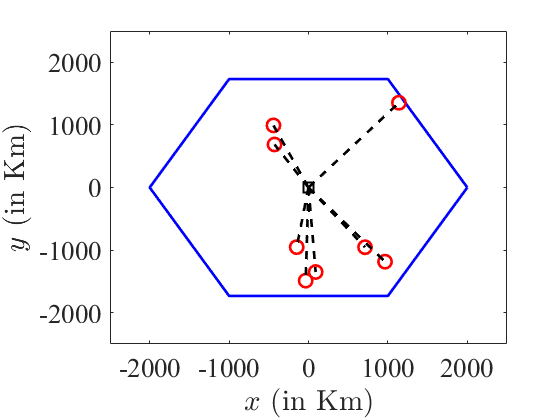

figure;

plot(x_cell,y_cell,'-b','linewidth',linewidth);
hold on;
plot(0,0,'sk','linewidth',linewidth,'markersize',markersize);
plot(x_user, y_user,'or','linewidth',linewidth,'markersize',markersize);
for k = 1:K
    plot([0 x_user(k)],[0 y_user(k)],'--k','linewidth',linewidth)
end
xlabel('$x$ (in Km)','fontname',fontname,'fontsize',fontsize,'interpreter','latex');
ylabel('$y$ (in Km)','fontname',fontname,'fontsize',fontsize,'interpreter','latex');

set(gca,'fontname',fontname,'fontsize',fontsize);
xlim([-1.25*R 1.25*R]);
ylim([-1.25*R 1.25*R]);

# Generating Channel Matrices

## Shadow Fading

Shadow fading is log-normally distributed

z = lognrnd(mu_shadow_fad,sigma_shadow_fad,K,1);                % Shadow fading

## Path Loss Calculation

Pass loss is computed using the COST-231 Hata model

[path_loss, path_loss_dB] = pathLoss(city,H_bs,H_user,r_bs_user,f_c);

path_loss_dB                                                                                          % Path loss

path_loss_dB =  -145.4249
 -137.9755
 -133.8383
 -141.3635
 -138.9757
 -142.7612
 -135.6282
 -142.3602


## Large-scale Fading Coefficient

The large-scale coefficient is independent of the small-scale effects and depend only the path loss and the shadow fading

beta    = z.*path_loss;                                           % Large-scale fading
beta_dB = 10.*log10(beta)                                         % Large-scale fading in dB

beta_dB =  -155.8084
 -148.8715
 -139.5912
 -138.3247
 -140.1306
 -148.0697
 -144.7735
 -150.3202


## Idependent Rayleigh Fading (Rich Scattering Fading)

G_rich = (randn(M,K) + 1i*randn(M,K))/sqrt(2);                      % Small-scale fading coefficient matrix
H_rich = G_rich*sqrt(diag(beta));                                   % Uplink channel matrix

## Uniformly Random LoS Fading

A = steeringVector(M,theta_user,d,lambda);

phi   = -pi + 2*pi*rand(K,1);                                     % Phase shift
phase = exp(1i*phi);                                               
Phase = repmat(phase.',M,1);                                

G_ur_los = Phase.*A;                                              % Small-scale fading coefficient matrix
H_ur_los = G_ur_los*sqrt(diag(beta));                             % Uplink channel matrix

## Orthogonality Deficiency

od_rich   = orthogonalityDeficiency(G_rich);                            % Orthogonality deficiency calculation
od_ur_los = orthogonalityDeficiency(G_ur_los);                          % Orthogonality deficiency calculation

disp(['Orthogonality Deficiency for Rich Sacattering Fading: ' num2str(od_rich)   newline ...
      'Orthogonality Deficiency for UR-LoS Fading:           ' num2str(od_ur_los)]);

Orthogonality Deficiency for Rich Sacattering Fading: 0.42047
Orthogonality Deficiency for UR-LoS Fading:           0.99972


# Functions

## User Position Generator

function [x,y] = userPositionGenerator(n_coord,R)

r = sqrt(3)/2*R;

aux_cord = rand(n_coord,1);

K_1 = sum(aux_cord < 1/3);
K_2 = sum(aux_cord < 2/3 & aux_cord > 1/3);

u = rand(n_coord,1);
v = rand(n_coord,1);

u_1 = u(1:K_1,1);
v_1 = v(1:K_1,1);

u_2 = u(K_1+1:K_1+K_2,1);
v_2 = v(K_1+1:K_1+K_2,1);

u_3 = u(K_1+K_2+1:n_coord,1);
v_3 = v(K_1+K_2+1:n_coord,1);

x_1 = -R/2*u_1 + R*v_1;
y_1 = r*u_1;

x_2 = -R/2*u_2 - R/2*v_2;
y_2 = -r*u_2 + r*v_2;

x_3 = R*u_3 - R/2*v_3;
y_3 = -r*v_3;

x = [x_1' x_2' x_3']';
y = [y_1' y_2' y_3']';

end


## Path Loss

function [L, L_dB] = pathLoss(city,h_bs,h_user,distance,frequency)

% COST-231 Hata Model

frequency = frequency/1e6;
distance = distance/1e3;

switch city
    case 'LARGE'
        if((150 <= frequency) && (frequency <= 200))
            C_h = 8.29*(log10(1.54*h_user)).^2 - 1.1;
        elseif((200 < frequency) && (frequency <= 2000))
            C_h = 3.2*(log10(11.75*h_user)).^2 - 4.97;
        else
        end
        C = 3;
    case 'MEDIUM'        
        C_h = 0.8 + (1.1*log10(frequency) - 0.7)*h_user - 1.56*log10(frequency);
        C = 0;
    case 'SMALL'
        C_h = 0.8 + (1.1*log10(frequency) - 0.7)*h_user - 1.56*log10(frequency);
        C = 0;
    otherwise
        error('Invalid type of city');
end

L_dB = -(46.30 + 33.90*log10(frequency) - 13.82*log10(h_bs) - C_h + ...
        (44.9 - 6.55*log10(h_bs))*log10(distance) + C);
    
L = 10.^(L_dB/10);

end

## Steering Vector

function steering_vector = steeringVector(M,theta,d,lambda)

m   = (0:M-1)';
tau = d*sin(theta)/lambda;
Tau = repmat(tau',M,1);

steering_vector = exp(-2*pi*1i*Tau.*repmat(m,1,size(theta,1)));

end

## Orthogonality Deficiency

function [od] = orthogonalityDeficiency(channel_matrix)

od = real(1 - det(channel_matrix'*channel_matrix)/prod(vecnorm(channel_matrix).^2));

end